# **Plotting in MATLAB**

This lecture will cover some of the plotting options in MATLAB. We will continue to use the Framingham dataset from the previous lecture. 

fram = readtable('../frmgham.xls');

For simplifying the following plotting exercises, we will just look at the first 100 patients in the dataset.

fram = head(fram,100);

# Plotting Datasets

There are many different ways to plot data in MATLAB and also several ways to generate these figures. Let's start by looking at the age data from our revised Framingham dataset.

age = fram.AGE;

Now that we have the age array saved as a variable, there are two ways to plot it:

    **Option 1: **Select the variable in the Workspace, go to Plots tab, and select the 2-D line plot. 

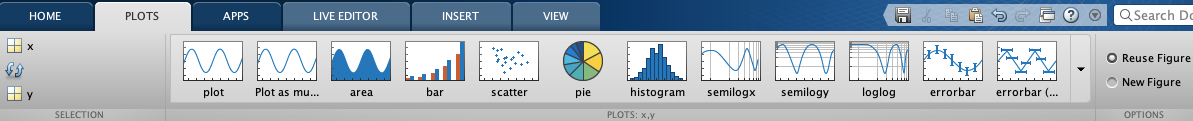

MATLAB will then create the plot for you in a new figure window and display the corresponding plotting command in the Command Window.

    **Option 2:** Use the *plot *command:

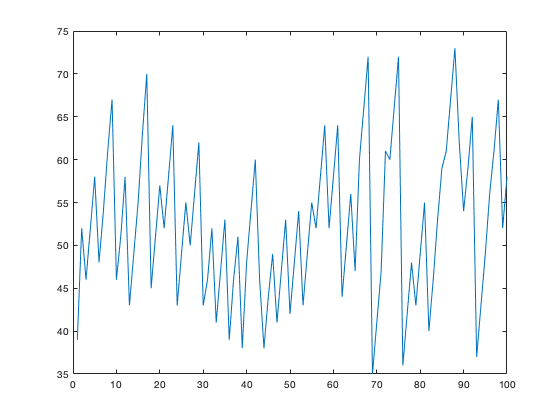

plot(age)

The figure includes the ages of all 100 patients, with age given on the y-axis and the index on the x-axis. Clearly we need to add some information to this plot and find a better way to display the data.

When viewing the plot in a figure window, we can use the Insert tab to add elements such as axis labels and titles. When you are done adding these features, there is an option to generate the code for these changes (click *File *then* Generate Code)*.

As we saw, plotting with one variable outputs the index on the x-axis. However, the *plot *command is typically used with two variables. Let's plot Age vs. BMI. First, we need to create the BMI array.

BMI = fram.BMI;

In addition to adding this variable, we should include axis labels and a title to our plot. Because we are using discrete data points, it also makes sense to use a different marker symbol as opposed to a line.

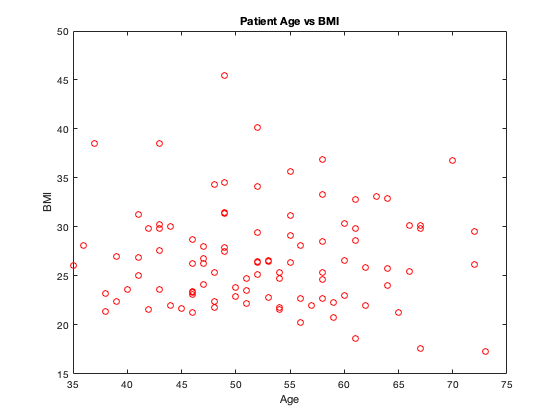

plot(age,BMI,'ro')
xlabel('Age')
ylabel('BMI')
title('Patient Age vs BMI')

### **Log-Log**

The log-log function simply generates a plot with a log scale on both axes. This may not necessarily be a useful tool for the variables in the Framingham dataset, but let's try it on the glucose data as an example. 

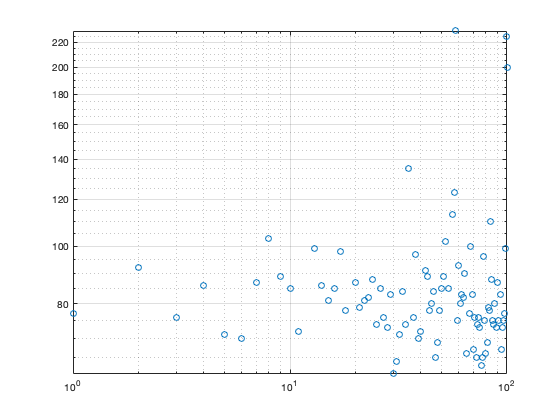

glucose = fram.GLUCOSE;
loglog(glucose,'o')
grid on

### **Bar Graphs**

Bar graphs are useful for comparing data from different groups or . 

Let's start with a simple example: use the *bar *command to create a graph showing the age of the first ten patients and another graph showing the BMI of the same group.

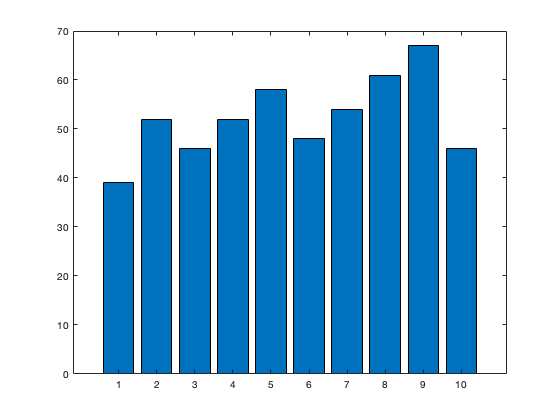

bar(age(1:10))

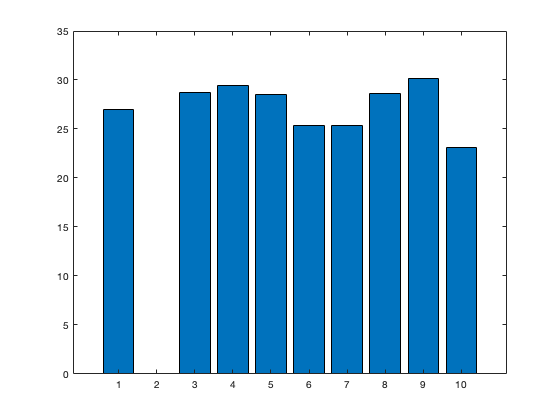

bar(BMI(1:10))

For a more complicated example, create a bar graph that looks at gender versus average cigarettes smoked per day. First, we must create our bar graph categories and specify the order in which they will display:

sex = categorical({'male','female'});
sex = reordercats(sex,{'male','female'})

sex = 1×2 categorical array
     male      female 


Next, extract the cigarettes per day data for each gender and find the mean values. In the Framingham dataset, males are represented by a 1 and females by a 2. Also, note that we must convert from a table to an array in order to use the *mean *function. 

male_cigs = table2array(fram(fram.SEX == 1,'CIGPDAY'));
female_cigs = table2array(fram(fram.SEX == 2,'CIGPDAY'));

mean_male_cigs = mean(male_cigs);
mean_female_cigs = mean(female_cigs);
mean_cigs = [mean_male_cigs,mean_female_cigs]

mean_cigs =    11.9388   10.5686


Finally, create the bar graph with the *bar *command. Let's make the bars blue and the bar width set to half of the available space.

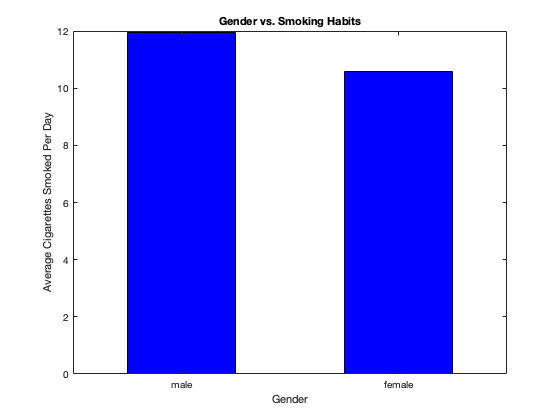

bar(sex,mean_cigs,0.5,'blue')
xlabel('Gender');
ylabel('Average Cigarettes Smoked Per Day');
title('Gender vs. Smoking Habits')

### **Pie Chart**

Pie charts are useful for looking at the composition of a group.

Let's create a pie chart which shows the gender distribution of the first 20 patients. The first step is to create an array which contains the quantity of each gender using the *nnz *function.

gender_count = [nnz(fram.SEX(1:20) == 1),nnz(fram.SEX(1:20) == 2)]

gender_count =      4    16


The *pie *function can then be used to display the elements of this array as a pie chart.

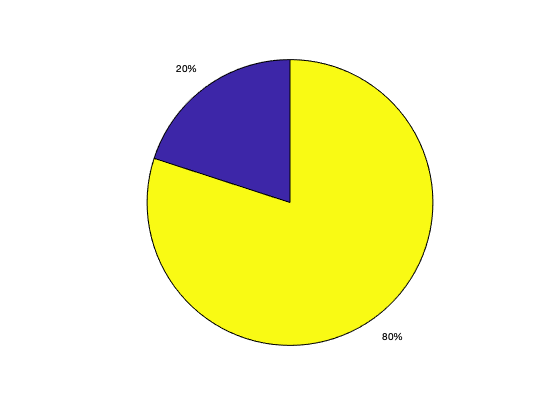

pie(gender_count)

Now we will make a pie chart which shows the education levels (1 to 4) for all 100 patients. Again, the first step is extracting these four values and putting them into an array. We will use a for loop to create this array.

education = (fram.educ);
i=1;
for i=1:4
    education_count(i)=nnz(education==i);
    i=i+1;
end
education_count

education_count =     34    33    18     9


It looks like the for loop worked, however we need to make sure that the sum of our array elements is equal to 100, as we want to make sure the entire patient group is represented in the pie chart

sum(education_count)

ans = 94

We know that the Framingham dataset contains some missing values. Confirm that this is the case with our education data.

nan = sum(isnan(education))

nan = 6

As expected, we are missing six data points, which would bring the total to 100. Add the missing data count to the education array so that it is incorported into the pie chart.

education_count(5) = nan;
education_count

education_count =     34    33    18     9     6


We are finally ready to make the pie chart. 

labels = {'1', '2', '3', '4','No Data'}

labels = 1×5 cell array
    {'1'}    {'2'}    {'3'}    {'4'}    {'No Data'}


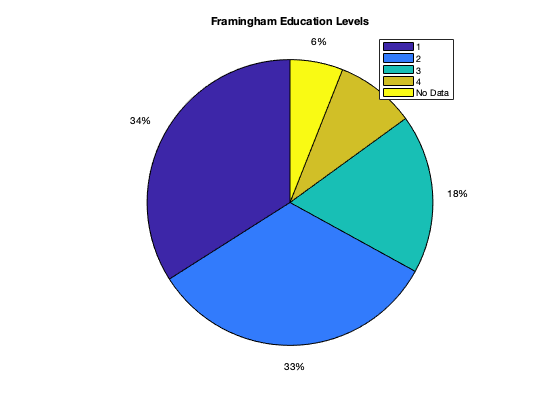

pie(education_count)
legend(labels)
title('Framingham Education Levels')

#### **Histograms**

Histograms are used to look at the distribution of continuous data. The dataset is displayed as a series of bins, which we can adjust to our preferences.

Use the *histogram *command to look at the distribution of age in the 100 patients (we created a 2-D line plot of this data earlier in the lesson).

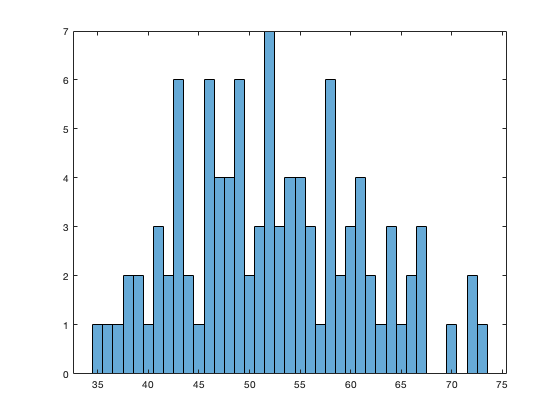

histogram(age)

The histogram plot is much more informative and easier to read than our original 2-D line plot from earlier in the lesson. We can easily see which ages are more common and determine if the distribution is fairly normal.

Next, create a histogram showing the heart rate distribution and assign it to a variable, *HR_histogram*. 

heart_rate = fram.HEARTRTE;
HR_histogram = histogram(heart_rate)

HR_histogram =   Histogram with properties:

             Data: [100×1 double]
           Values: [3 19 36 23 13 4 2]
          NumBins: 7
         BinEdges: [50 60 70 80 90 100 110 120]
         BinWidth: 10
        BinLimits: [50 120]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


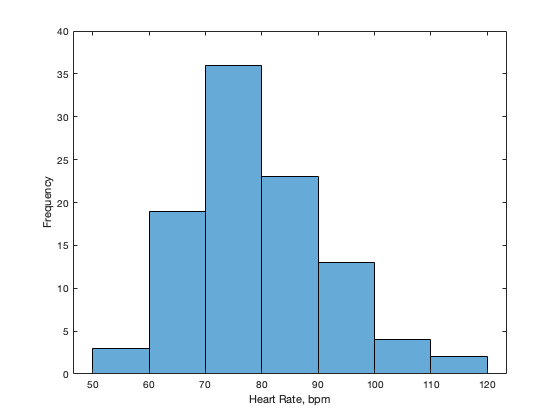

xlabel('Heart Rate, bpm')
ylabel('Frequency')

By assigning the histogram to a variable, we can now use dot notation to adjust the plot properties. Break down the data into 10 bins (using *.NumBins*) and change the bin color (using *.FaceColor*). 

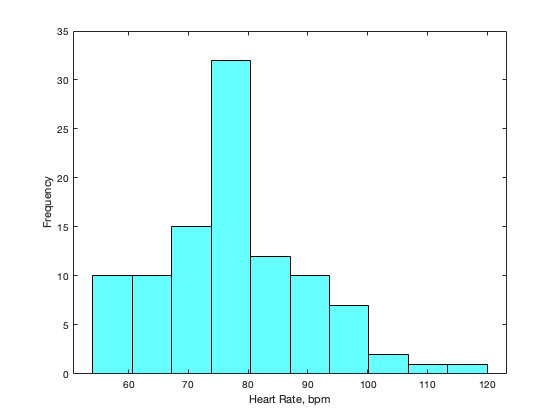

HR_histogram =   Histogram with properties:

             Data: [100×1 double]
           Values: [10 10 15 32 12 10 7 2 1 1]
          NumBins: 10
         BinEdges: [54 60.6000 67.2000 73.8000 80.4000 87 93.6000 100.2000 106.8000 113.4000 120]
         BinWidth: 6.6000
        BinLimits: [54 120]
    Normalization: 'count'
        FaceColor: [0 1 1]
        EdgeColor: [0 0 0]

  Show all properties


HR_histogram.NumBins = 10;
HR_histogram.FaceColor = 'cyan'

Another useful feature of the *histogram* command in MATLAB is the ability to compare two distributions in the same figure. For example, we can look at the distribution of total cholesterol in males versus females. First, create an array containing the cholesterol data for males and plot a histogram of the data with 10 bins.

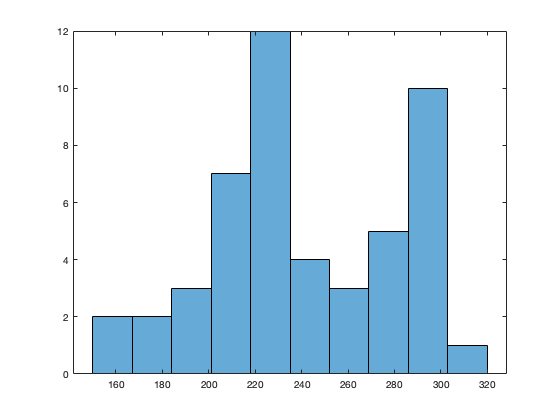

male_cholesterol = fram.TOTCHOL(fram.SEX==1);
histogram(male_cholesterol, 10)

Next, we will do the same for the female cholesterol data and use the *hold on *function to add the histogram to our previous plot.

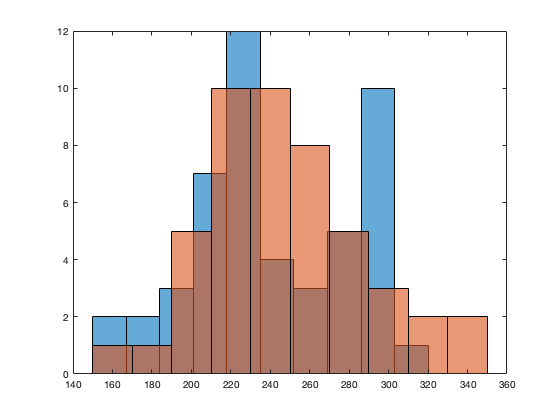

female_cholesterol = fram.TOTCHOL(fram.SEX == 2);
hold on 
histogram(female_cholesterol, 10)
hold off

### Boxplots

Boxplots are also helpful for looking at data distribution. In addition to showing the shape of the distribution, boxplots display the median value, the interquartile range, minimum/maxmimum values, and outlier points.

Use the *boxplot *command to examine total cholesterol versus sex.

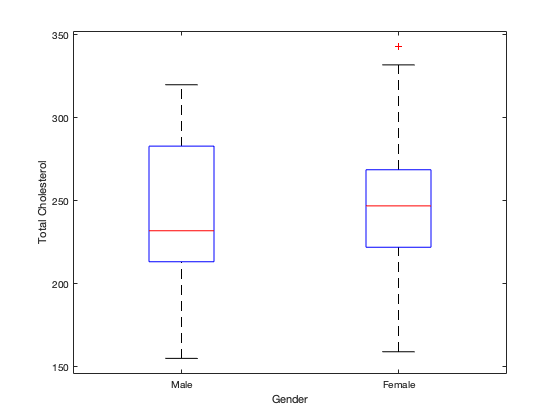

boxplot(fram.TOTCHOL,fram.SEX,'Labels',{'Male','Female'})
xlabel('Gender')
ylabel('Total Cholesterol')

As another example, create a boxplot showing how blood glucose varies between the patients without diabetes (0) and with diabetes (1).

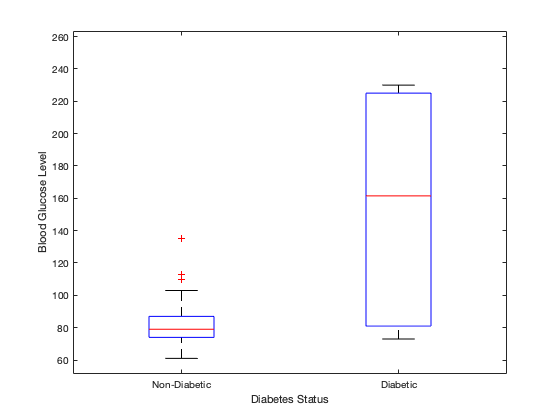

boxplot(fram.GLUCOSE,fram.DIABETES,'Labels',{'Non-Diabetic','Diabetic'})
xlabel('Diabetes Status')
ylabel('Blood Glucose Level')

### Correlation

MATLAB has many tools for examining the relationship between variables. Use the *lsline *command to plot the least squares regression line for systolic and diastolic blood pressure. 

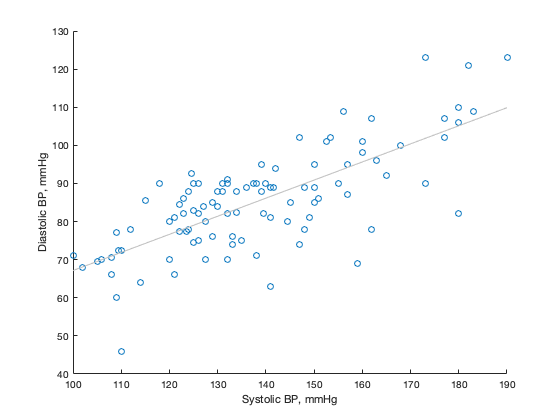

sys = fram.SYSBP;
dia = fram.DIABP;
scatter(sys,dia)
lsline
xlabel('Systolic BP, mmHg');
ylabel('Diastolic BP, mmHg');

Next, use the *corr *function to calculate the correlation coefficient between systolic and diastolic blood pressure. The correlation coefficient, *r, *indicates the strength and direction of the relationship between the two variables.

r = corr(sys,dia)

r = 0.7429

We can also create a linear fit model for between the two variables using the *fitlm* command:

lrm = fitlm(sys,dia)

lrm = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat      pValue  
                   ________    ________    ______    _________

    (Intercept)     19.679       6.0262    3.2656    0.0015057
    x1             0.47475     0.043212    10.986     8.88e-19


Number of observations: 100, Error degrees of freedom: 98
Root Mean Squared Error: 9.1
R-squared: 0.552,  Adjusted R-Squared: 0.547
F-statistic vs. constant model: 121, p-value = 8.88e-19

The output shows the model formula, the coefficients, and model summary. The coefficient of determination, r^2, is given in the model summary, but it can also be found with the below command:

r2 = lrm.Rsquared.Ordinary

r2 = 0.5519

Notice that the coefficient of determine, *r*, is also equivalent to the coefficient of correlation raised to the power of 2:

r .^ 2

ans = 0.5519

The coefficient of determination measures the amount of variance of one variable that can be explained by the other. In our example, r^2 is equal to 0.506. This means that 50.6% of the variance in the diastolic blood pressure can be explained by the systolic blood pressure data. This can be used as an indicator for how good of a fit the least squares regression line is. 

For another example, we will determine the coefficients of correlation and determination between BMI and blood glucose levels. 

Previous work with these variables showed that there is data missing from both the BMI and blood glucose datasets. The *corr *function will not work with arrays that contain NaN*. *We can remove these rows containing NaN with the `rmmissing` command.

missing_rows = [find(isnan(BMI)); find(isnan(glucose))]

Now that the rows containing Nan have been found, we have to remove these rows from the two arrays.

new_BMI = BMI;
new_BMI(missing_rows,:) = []

new_BMI =    26.9700
   28.7300
   29.4300
   28.5000
   25.3400
   25.3400
   28.5800
   30.1800
   23.1000
   23.4800


new_glucose = glucose;
new_glucose(missing_rows,:) = []

new_glucose =     77
    76
    86
    71
    70
    87
   103
    89
    85
    72


Once the missing data has been removed, we can calculate the coefficients of correlation and determination.

r_BMI_glucose = corr(new_BMI, new_glucose)

r_BMI_glucose = 0.3385

r2_BMI_glucose = r_BMI_glucose .^ 2

r2_BMI_glucose = 0.1146

The correlation between these two variables is not nearly as strong as in the previous example with the systolic and diastolic blood pressures. Create a scatter plot and least-squares line to better visualize the relationship between BMI and blood glucose levels.

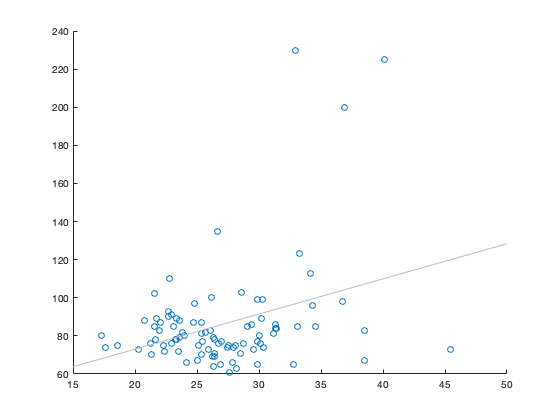

scatter(new_BMI, new_glucose)
lsline

## Visualizing Distributions

The `gscatter` function allows us to plot two variables against each other, such as Glucose and BMI, and then separate those data points by group. The grouping variable must be in the form of a categorical variable, such as Diabetes.

Use `gscatter` to plot glucose versus BMI, grouped by diabetes.

gscatter(fram.GLUCOSE, fram.BMI, fram.DIABETES)
xlabel('Glucose')
ylabel('BMI')
legend('Non-Diabetic','Diabetic')

In this example, `gscatter` makes it easy to see that essentially all of the data points at high glucose levels belong to patients with diabetes.

Repeat this process with systolic blood pressure versus total cholesterol, grouped by cardiovascular disease.

gscatter(fram.SYSBP,fram.TOTCHOL,fram.CVD)
xlabel('Systolic Blood Pressure')
ylabel('Total Cholesterol')

Unlike the last example, there aren't any apparents trends between the data groups. Upon close inspection, it appears that a slight majority of patients with higher heart rates also suffered from CVD. In some cases, we may want to use this tool to help confirm that the data points are equally distributed throughout the different categories.

# Further Practice

### Distribution of Blood Glucose Levels

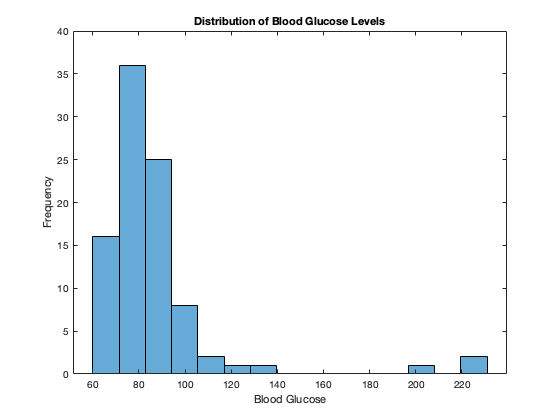

histogram(glucose,15)

title('Distribution of Blood Glucose Levels')
xlabel('Blood Glucose')
ylabel('Frequency')

### Boxplot: Gender versus Heart Rate

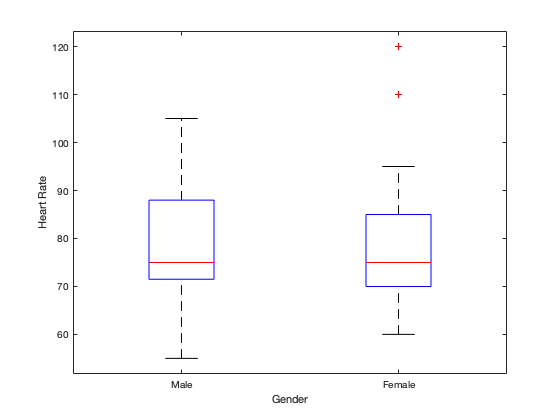

gender = fram.SEX;
boxplot(heart_rate, gender,'Labels',{'Male','Female'})
ylabel('Heart Rate')
xlabel('Gender')

### Education vs BMI

What is best way to show this relationship?

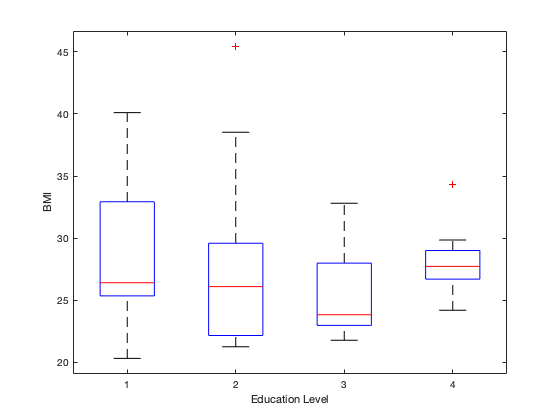

boxplot(BMI,education)
ylabel('BMI')
xlabel('Education Level')